% Read the dataset from the path
data = readtable('C:\Users\salem\Downloads\dataAI.csv');

% Remove any rows with missing values
data = rmmissing(data);

% Normalize numeric columns to have values between 0 and 1
for i = 1:width(data)
    if isnumeric(data{:, i})
        data{:, i} = (data{:, i} - min(data{:, i})) / (max(data{:, i}) - min(data{:, i}));
    end
end

% Initialize a logical array to mark rows with outliers
outliers = false(height(data), 1);

% Define the Z-score threshold for identifying outliers
zThreshold = 3;

% Detect and mark outliers across all numeric columns
for i = 1:width(data)
    if isnumeric(data{:, i})
        zScores = (data{:, i} - mean(data{:, i})) ./ std(data{:, i});
        outliers = outliers | (abs(zScores) > zThreshold);
    end
end

% Remove rows identified as having outliers
data(outliers, :) = [];

% Optionally, save the cleaned and processed data to a new file
writetable(data, 'C:\Users\salem\Downloads\cleaned_data.csv');


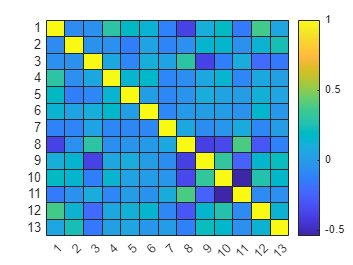


data = readtable( 'C:\Users\salem\Downloads\cleaned_data.csv');


% Step 2: Renaming Columns
data.Properties.VariableNames{'cp'} = 'ChestPainType';
data.Properties.VariableNames{'trestbps'} = 'RestingBloodPressure';
data.Properties.VariableNames{'chol'} = 'SerumCholestoral';
data.Properties.VariableNames{'fbs'} = 'FastingBloodSugar';
data.Properties.VariableNames{'restecg'} = 'RestingECG';
data.Properties.VariableNames{'thalach'} = 'MaxHeartRate';
data.Properties.VariableNames{'exang'} = 'ExerciseInducedAngina';
data.Properties.VariableNames{'oldpeak'} = 'STDepression';
data.Properties.VariableNames{'slope'} = 'SlopeSTSegment';
data.Properties.VariableNames{'ca'} = 'NumMajorVessels';
data.Properties.VariableNames{'thal'} = 'Thal';

% Step 3: Exploratory Data Analysis (EDA)
sum(ismissing(data));
correlationMatrix = corr(table2array(data(:,1:end-1)));
heatmap(correlationMatrix, 'Colormap', parula, 'ColorbarVisible', 'on');


% Step 4: Calculating Age Statistics
minAge = min(data.age);
maxAge = max(data.age);
meanAge = mean(data.age);
fprintf('Min Age: %d, Max Age: %d, Mean Age: %.2f\n', minAge, maxAge, meanAge);

Min Age: 0, Max Age: 1, Mean Age: 0.53


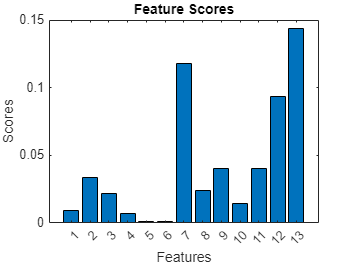



% Step 6: Feature Selection using ANOVA F-value
X = data{:, 1:end-1};
y = data.target;
[~, scores] = fscmrmr(X, y);
bar(scores);
xlabel('Features');
ylabel('Scores');
title('Feature Scores');


% Step 7: Data Preprocessing and Scaling
X = data{:, {'age', 'sex', 'ChestPainType', 'Thal', 'ExerciseInducedAngina', 'SlopeSTSegment', 'NumMajorVessels', 'MaxHeartRate', 'STDepression'}};
X = zscore(X);

% Step 8: Splitting the Data
cv = cvpartition(size(data, 1), 'HoldOut', 0.3);
X_train = X(training(cv), :);
y_train = y(training(cv));
X_test = X(test(cv), :);
y_test = y(test(cv));

% Step 9: Model Training and Evaluation
mdl = fitcknn(X_train, y_train, 'NumNeighbors', 5);
y_pred = predict(mdl, X_test);
accuracy = sum(y_pred == y_test) / length(y_test);
fprintf('Accuracy: %.2f\n', accuracy);

Accuracy: 0.90


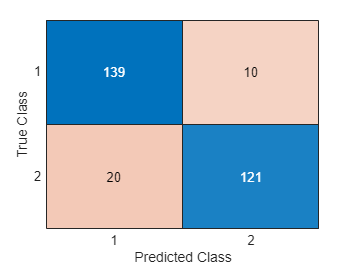

confMat = confusionmat(y_test, y_pred);
confusionchart(confMat);



% Step 10: Handling Imbalanced Data Using Simple Oversampling

% Extracting labels and corresponding indices for minority and majority classes
labels = data.target; % Ensure this column name matches your label column
[uniqueClasses, ~, classIndices] = unique(labels);
classCounts = accumarray(classIndices, 1);

% Find minority and majority class
[minCount, minorityClassIndex] = min(classCounts);
[maxCount, majorityClassIndex] = max(classCounts);

% Separate the data based on class
minorityData = data(labels == uniqueClasses(minorityClassIndex), :);
majorityData = data(labels == uniqueClasses(majorityClassIndex), :);

% Oversample the minority class by random sampling with replacement
oversampledMinorityData = minorityData(randsample(size(minorityData, 1), maxCount - minCount, true), :);

% Combine the oversampled minority data with the original majority data
balancedData = [majorityData; oversampledMinorityData];

% Prepare features and target from balanced dataset
X_balanced = balancedData{:, 1:end-1}; % Assuming the last column is not the target
y_balanced = balancedData.target; % Ensure this matches your target column name

% Standardize features
X_balanced = zscore(X_balanced);

% Split data into training and testing sets
cv_balanced = cvpartition(size(X_balanced, 1), 'HoldOut', 0.3);
X_train_balanced = X_balanced(training(cv_balanced), :);
y_train_balanced = y_balanced(training(cv_balanced));
X_test_balanced = X_balanced(test(cv_balanced), :);
y_test_balanced = y_balanced(test(cv_balanced));

% Model Training and Evaluation on balanced data
mdl_balanced = fitcknn(X_train_balanced, y_train_balanced, 'NumNeighbors', 5);
y_pred_balanced = predict(mdl_balanced, X_test_balanced);
accuracy_balanced = sum(y_pred_balanced == y_test_balanced) / length(y_test_balanced);
fprintf('Accuracy after balancing: %.2f\n', accuracy_balanced);

Accuracy after balancing: 0.97


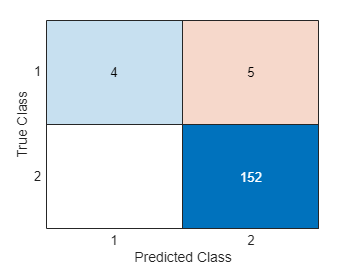

confMat_balanced = confusionmat(y_test_balanced, y_pred_balanced);
confusionchart(confMat_balanced);